# Second-Order Lab: Second-Order Linear DEs in MATLAB

In this lab, you will learn how to use `iode` to plot solutions of second-order ODEs. You will also learn to classify the behaviour of different types of solutions.

Moreover, you will write your own Second-Order ODE system solver, and compare its results to those of `iode`.

Opening the m-file lab5.m in the MATLAB editor, step through each part using cell mode to see the results.

There are seven (7) exercises in this lab that are to be handed in on the due date of the lab.

## Student Information

## Iode for Second-Order Linear DEs with constant coefficients

In the `iode` menu, select the `Second order linear ODEs` module. It opens with a default DE and a default forcing function `f(t) = cos(2t)`. The forcing function can be plotted along with the solution by choosing `Show forcing function` from the `Options` menu.

Use this module to easily plot solutions to these kind of equations.

There are three methods to input the initial conditions:

Method 1. Enter the values for `t0`, `x(t0)`, and `x'(t0)` into the `Initial conditions` boxes, and then click `Plot solution`.

Method 2. Enter the desired slope `x'(t0)` into the appropriate into the `Initial conditions` box, and then click on the graph at the point `(t0,x(t0))` where you want the solution to start.

Method 3. Press down the left mouse button at the desired point `(t0,x(t0))` and drag the mouse a short distance at the desired slope `x'(t0)`. When you release the mouse button, `iode` will plot the solution.

## Growth and Decay Concepts

We want to classify different kinds of behaviour of the solutions. We say that a solution:

`grows` if its magnitude tends to `infinity` for large values of `t`, that is, if either the solution tends to $+\infty$ or $-\infty$,

`decays` if its magnitude converges to `0` for large values of `t`,

`decays while oscillating` if it keeps changing sign for large values of `t` and the amplitude of the oscillation tends to zero,

`grows while oscillating` if it keeps changing sign for large values of `t` and the amplitude of the oscillation tends to infinity.

## Example

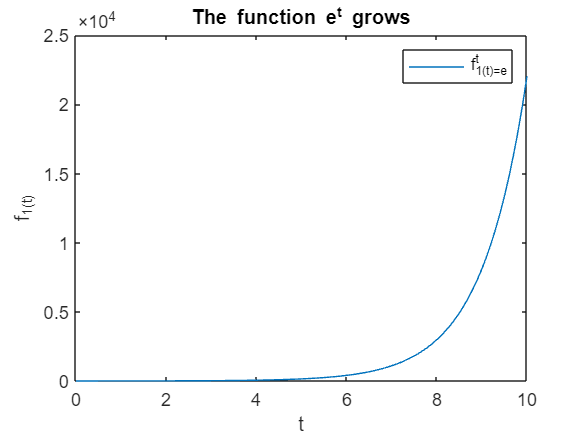

Time = 0:0.1:10;

% Example 1
figure();
y1 = exp(Time);
plot(Time,y1)

% Annotate the figure
xlabel('t');
ylabel('f_1(t)');
title('The function e^t grows');
legend('f_1(t)=e^t');

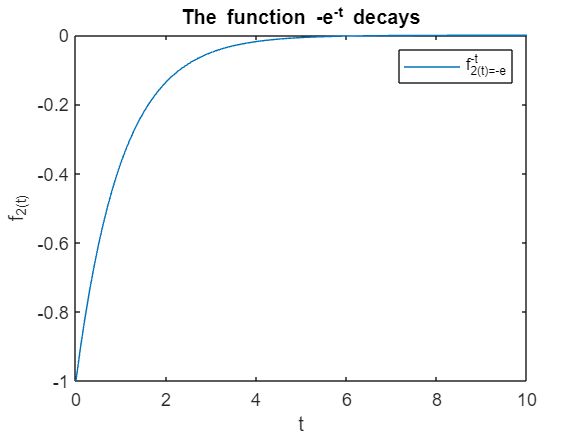




% Example 2
figure();
y2 = -exp(-Time);
plot(Time,y2)

% Annotate the figure
xlabel('t');
ylabel('f_2(t)');
title('The function -e^{-t} decays');
legend('f_2(t)=-e^{-t}');

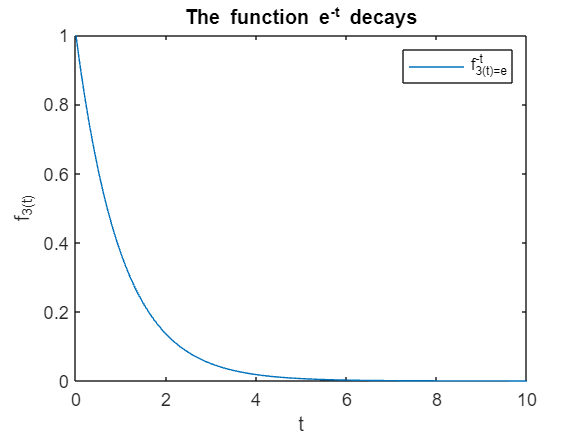




% Example 3
figure();
y3 = exp(-Time);
plot(Time,y3)

% Annotate the figure
xlabel('t');
ylabel('f_3(t)');
title('The function e^{-t} decays');
legend('f_3(t)=e^{-t}');

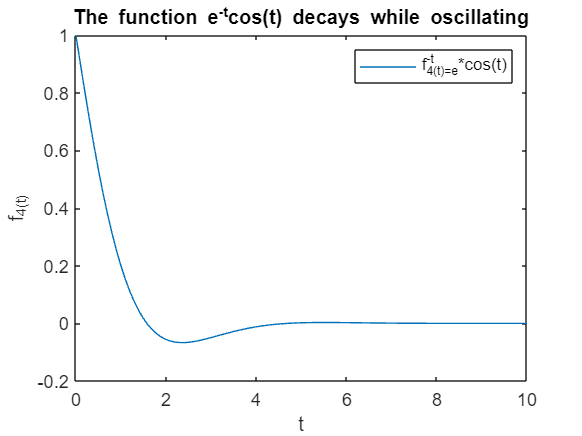




% Example 4
figure();
y4 = exp(-Time).*cos(Time);
plot(Time,y4)

% Annotate the figure
xlabel('t');
ylabel('f_4(t)');
title('The function e^{-t}cos(t) decays while oscillating');
legend('f_4(t)=e^{-t}*cos(t)');

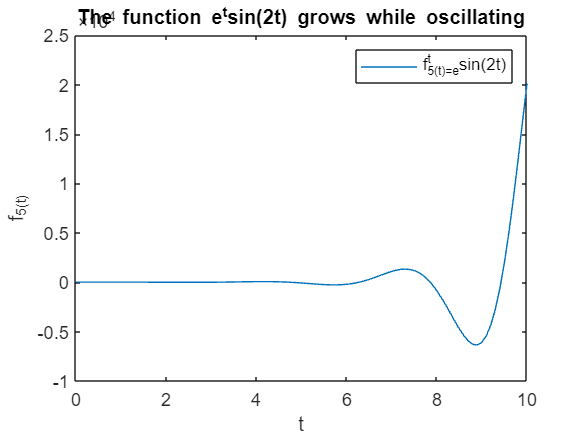




% Example 5
figure();
y5 = exp(Time).*sin(2*Time);
plot(Time,y5)

% Annotate the figure
xlabel('t');
ylabel('f_5(t)');
title('The function e^{t}sin(2t) grows while oscillating');
legend('f_5(t)=e^{t}sin(2t)');

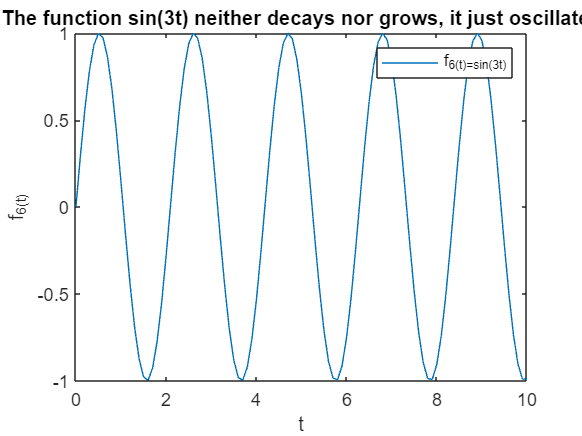




% Example 6
figure();
y6 = sin(3*Time);
plot(Time,y6)

% Annotate the figure
xlabel('t');
ylabel('f_6(t)');
title('The function sin(3t) neither decays nor grows, it just oscillates');
legend('f_6(t)=sin(3t)');




% |Remark.| A function which |grows while oscillating| doesn't |grow|,
% because it keeps changing sign, so it neither tends to $+\infty$ nor to
% $-\infty$.

## Exercise 1

Objective: Use `iode` to solve second-order linear DEs. And classify them.

Details: Consider the ODE:

(a) Use `iode` to plot six (6) numerical solutions of this equation with "random" initial data (use Method 3 above) and press-and-drag at various initial points, with some of the slopes being positive and some negative)

Use only initial points in the part of the window where `0<t<1` and `-1<x<1` and take all initial slopes between `-3` and `+3`.

Change the window to `[0,10]x[-3,3]`. Attach a cropped screenshot to your answers file.

(b) Based on the results of (a), state what percentage of solutions decay, grow, grow while oscillating, or decay while oscillating.

% Decay: 0%
% Grow: 0% 
% Grow while oscillating: 0%
% Decay while oscillating: 100%

(c) Solve the DE and write the exact solution. Explain why this justifies your answer in (b).

% The general solution(exact solution) is y(t) = e^(-0.5t)*(c1*cos(-2t) +
% c2*sin(-2t)). This shows that as time goes positive infinity, this will reach the
% 0 due to e^(-0.5t). When the power of e goes to negative infinity, the
% whole functin will go to 0.. The reason why they are oscillating,
% decaying is because of sinusoidal oscillations. As t vaires, they will
% behave between -1 and 1, therefore, cos and sin function makes this
% oscillating. 

% However, when c1 and c2 both are 0, this will go to 0 without
% osicliating. 

## Exercise 2

Consider the ODE:

Repeat (a), (b), (c) from Exercise 1 with this DE.

% (b)
% Decay: 0%
% Grow: 100% 
% Grow while oscillating: 0%
% Decay while oscillating: 0%
% (c)
% The general solution (Exact sol'n) is y(t) = c1*e^(((-2-sqrt(3))/2)*t)+c2*e^(((2-sqrt(3))/2)*t)
% As you can see from here, there is no sinusoidal oscillations because
% there is no sin or cosin function in general solution. Also,
% c1*e^(((-2-sqrt(3))/2)*t) will go to 0, when time approaches positive
% infinity(as power of e is negative). However, c2*e^(((2-sqrt(3))/2)*t), this will go to infinity
% when time approches positive infinity. (as power of e is positive) Therefore,
% c2*e^(((2-sqrt(3))/2)*t), this is dominant function, therefore, whole
% thing will go positive infinity as time goes to positive infinity. (which
% is grow) 
% Exception: When c1 = c2 = 0, then it will be just 0/ 
% Also when c2 = 0, c1 not equal to zero, this will be approaching 0 . as t
% goes to positive infinity. 

## Exercise 3

Consider the ODE:

Repeat (a), (b), (c) from Exercise 1 with this DE.

% (b)
% Decay: 100%
% Grow: 0% 
% Grow while oscillating: 0%
% Decay while oscillating: 0%
% (c)
% The general solution (Exact sol'n) is y(t) = c1*e^(((-sqrt(2)-sqrt(3))/2)*t)+c2*e^(((sqrt(2)-sqrt(3))/2)*t)
% As you can see from here, there is no sinusoidal oscillations because
% there is no sin or cosin function in general solution. Therefore, no oscillating. 
% Also, c1*e^(((-sqrt(2)-sqrt(3))/2)*t) will go to 0, when time approaches positive
% infinity. And, cc2*e^(((sqrt(2)-sqrt(3))/2)*t), this will go to zero
% when time approches positive infinity. 
% The reason why both of them go to 0 is because of power of e, and in both
% terms, they are all negative. Therefore, they both go to 0 when t goes to
% positive infinity. 
% Same as negative infinity, both will go to 0 when time approaches
% negative infinity, which will never happen in real life. 
% Therefore, both function will go to zero without ozcillating, therefore,
% this is 100% decay.

% when c1 = 0, c2 = 0, that will be just 0, this is exceptional case. 

## Example

Consider the ODE:

The solution is

From this, it is easy to see that all solutions decay while oscillating.

Similarly, for the equation 

The solution is

which grows while oscillating.

## Exercise 4

Consider the fourth-order ODE:

(a) Find the general solution for this problem. You can use MATLAB to find the roots of the characteristic equation numerically with `roots`.

% y = [ 1 2 6 2 5 0 ];
% roots(y)
  
   % 0.0000 + 0.0000i
   % -1.0000 + 2.0000i
   % -1.0000 - 2.0000i
   % 0.0000 + 1.0000i
   % 0.0000 - 1.0000i
   % Therefore, the complementary solution is, y_h = e^(-t)*(c1*cos(2t) +
   % c2*sin(2t)) + c3*cos(t) + c4*sin(t)
   % as there this is homogenous equation, therefore, complementary
   % solution is indeed general solution in this case.
   % Therefore, general solution is y = e^(-t)*(c1*cos(2t) +
   % c2*sin(2t)) + c3*cos(t) + c4*sin(t)

(b) Predict what percentage of solutions with random initial data will grow, decay, grow while oscillating, and decay while oscillating. Explain.

   % To see how it behaves, this is important to see how each function will
   % behave as t approaches positive infinity. First of all, e^(-t)*(c1*cos(2t) +
   % c2*sin(2t)), this will approach 0 as t -> positive infinity. The
   % reason behind is because the power of e is negative. However,
   % c3*cos(t) + c4*sin(t), this is sinusolidal oscillation, therefore, as
   % t -> positive infinity, they will just oscilating forever. As this
   % won't decay or grow at all, c3*cos(t) + c4*sin(t) is dominant,
   % therefore, this will behave as just osciliation as t -> postive
   % infinity. 

    % Decay: 0%
    % Grow: 0% 
    % Grow while oscillating: 0%
    % Decay while oscillating: 0%
    % Oscillating: 100%

    % One possible exception is, when c3 and c4 has different sign, but
    % same magnitude. Then, c3*cos(t) + c4*sin(t) = 0,(also trigonometirc 
    % term can be expressed as a linear combination. which will tend to zero as t -> positiv infinity.) 
    % which will lead to "decay" while oscilating, due to e^(-t)*(c1*cos(2t) +
    % c2*sin(2t)). This will also go to 0,  therefore, it will go to 0 at
    % the end.

## Exercise 5

Objective: Classify equations given the roots of the characteristic equation.

Details: Your answer can consist of just a short sentence, as `grows` or  `decays while oscillating`.

Consider a second-order linear constant coefficient homogeneous DE with `r1` and `r2` as roots of the characteristic equation.

Summarize your conclusions about the behaviour of solutions for randomly chosen initial data when.

(a) `0 < r1 < r2`

(b) `r1 < 0 < r2`

(c) `r1 < r2 < 0`

(d) `r1 = alpha + beta i` and  `r2 = alpha - beta i` and `alpha < 0`

(e) `r1 = alpha + beta i` and  `r2 = alpha - beta i` and `alpha = 0`

(f) `r1 = alpha + beta i` and  `r2 = alpha - beta i` and `alpha > 0`

    % (a) Grows
    % (b) Grows 
    % (c) Decays
    % (d) Decays while oscillating
    % (e) Oscillating 
    % (f) Grows while oscillating 

   % Conclusion: When r1 < 0 < r2, this will grow since dominant function will go positive infinity.
   % therefore, whole thing will go positive infinity as time goes to positive infinity. (which
% is grow
   % when both are positive, it will grow, and both are negative, it will
   % decay. When you have complex term in the ccharacteristic equation,
   % this will have osciliating, but the sign of alpha will decide the
   % behaviour of the fnc. 


## Numerical Methods for Second-Order ODEs

One way to create a numerical method for second-order ODEs is to approximate derivatives with finite differences in the same way of the Euler method.

This means that we approximate the first derivative by:

and

By writing these approximations into the ODE, we obtain a method to get `y[n+1]` from the previous two steps `y[n]` and `y[n-1]`.

The method for approximating solutions is:

1. Start with `y[0]=y0`

2. Then we need to get `y[1]`, but we can't use the method, because we don't have two iterations `y[0]` and `y[-1]`(!!). So we use Euler to get

y1 is the slope given by the initial condition

3. Use the method described above to get `y[n]` for `n=2,3,...`.

## Exercise 6

Objective: Write your own second-order ODE solver.

Details: Consider the second-order ODE

Write a second-order ODE solver using the method described above.

This m-file should be a function which accepts as variables (t0,tN,y0,y1,h), where t0 and tN are the start and end points of the interval on which to solve the ODE, y0, y1 are the initial conditions of the ODE, and h is the stepsize. You may also want to pass the functions into the ODE the way `ode45` does (check MATLAB lab 2). Name the function DE2_<UTORid>.m.

Note: you will need to use a loop to do this exercise. 

## Exercise 7

Objective: Compare your method with `iode`

Details: Use `iode` to plot the solution of the ODE  `y'' + exp(-t/5) y' + (1-exp(-t/5)) y = sin(2*t)` with the initial conditions  `y(0) = 1, y'(0) = 0`

Use the window to `[0,20]x[-2,2]` Without removing the figure window, plot your solution (in a different colour), which will be plotted in the same graph. 

Comment on any major differences, or the lack thereof.

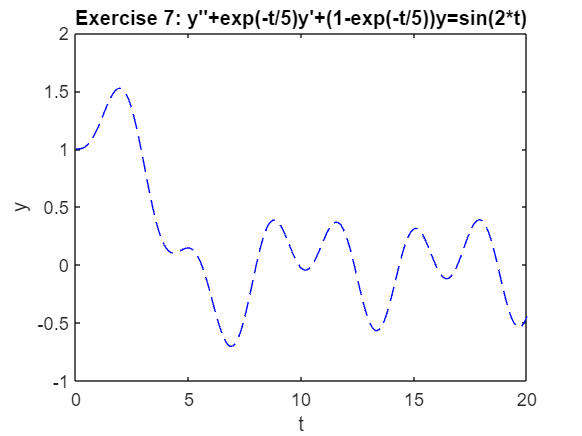

t0=0;
tN=20;
y0=1;
y1=0;
h=0.01;

f = @(time,y_one,y) -exp(-time/5)*y_one-(1-exp(-time/5))*y+sin(2*time); % the function expressed in form y” = f(t, y, y’)

[Time, y]=DE2_shinja19(f, t0, tN, y0, y1,h);
plot (Time,y, "b--");
xlabel("t");
ylabel('y');title("Exercise 7: y''+exp(-t/5)y'+(1-exp(-t/5))y=sin(2*t)");


% There is no major difference when i set mine to h = 0.01 which is really samll step size. 
% However, when both are h = 0.1, then the plots are slightly different from each other.
% This may due to comparison between runge-kunta method and my solver. As
% my solver is based on the euler method, this has less accuracy than
% runge-kutta method. 
% "One way to create a numerical method for second-order ODEs is to
% approximate derivatives with finite differences in the same way of the
% Euler method." 